rng(42);

% Number of samples and features
numSamples = 100;
numFeaturesX = 50;
numFeaturesY = 200;
numFeaturesZ = 30;

% Generate random data matrices X, Y, Z
X = randn(numSamples, numFeaturesX);
Y = randn(numSamples, numFeaturesY);
Z = randn(numSamples, numFeaturesZ);

% Sparsity regularization parameters
cu = 5;
cv = 5;
cw = 5;
% Convergence threshold and iteration limit
e = 1e-5;
itr_lim = 1000;

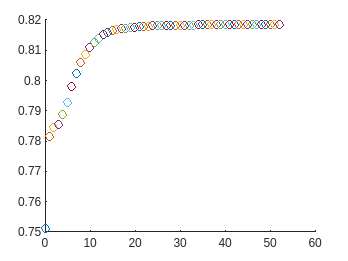

SPLS: itr: 53    diff: 9.84e-06    dim_u: 44    dim_v: 42


[u, v, success] = cv_spls(X, Y, cu, cv, e, itr_lim);

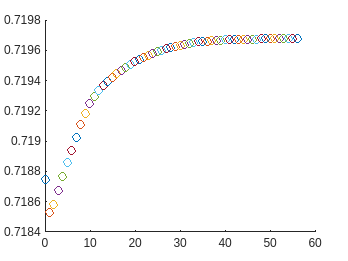

SPLS: itr: 57    diff: 9.51e-06    dim_u: 40    dim_v: 30


[u1, w1, success] = cv_spls(X, Z, cu, cw, e, itr_lim);

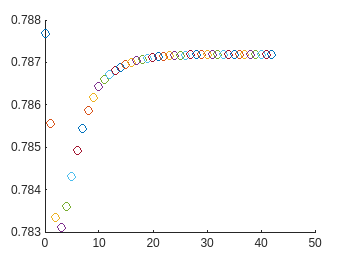

SPLS: itr: 43    diff: 8.63e-06    dim_u: 39    dim_v: 30


[v2, w2, success] = cv_spls(Y, Z, cv, cw, e, itr_lim);

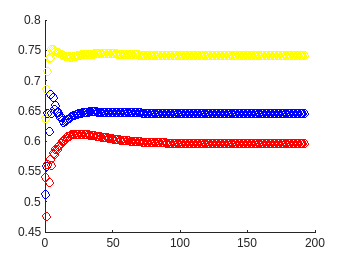

SPLS: itr: 193    diff: 9.71e-06    dim_M1: 41    dim_M2: 38    dim_M3: 30    


matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;

cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

% Run generalized SPLS
[weights, covariances, success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 1);

rng(42);

% Number of samples and features
numSamples = 100;
numFeaturesX = 50;
numFeaturesY = 200;
numFeaturesZ = 30;

% Generate random data matrices X, Y, Z
X = randn(size(gX_table_s));
Y = randn(size(gY_table_s));
Z = randn(size(gZ_table_s));
%%
%% gsPLS prep
%matrices{1} = table2array(gX_table_s);
%matrices{2} = table2array(gY_table_s);
%matrices{3} = table2array(gZ_table_s);
matrices{1} = X;
matrices{2} = Y;
matrices{3} = Z;

cu = 2;
cv = 2;
cw = 2;
e = 1e-5;
itr_lim = 1000;
cs = [cu, cv, cw];
num_matrices = 3;
% Design matrix to model relationship between matrices: Equal influence between matrices 
gs = (1/(num_matrices-1)) * (ones(num_matrices) - eye(num_matrices));

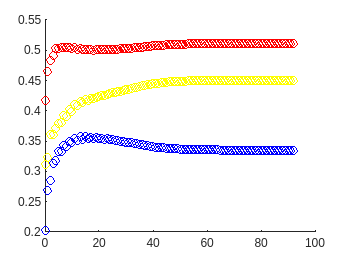

SPLS: itr: 93    diff: 9.51e-06    dim_M1: 34    dim_M2: 8    dim_M3: 28    


cu = 5;
cv = 2;
cw = 10;
e = 1e-5;
itr_lim = 1000;
cs = [cu, cv, cw];
% Run generalized SPLS
[weights, covariances, success] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 1);

result_table = cell2table(cell(0,11), 'VariableNames',{'cu', 'cv', 'cw', 'corr_XY', 'corr_XZ', 'corr_YZ', 'spls_itr', 'diff', 'dim_m1', 'dim_m2', 'dim_m3'});
cu_range = 1:1:sqrt(size(matrices{1},2));
cv_range = 1:1:sqrt(size(matrices{2},2));
cw_range = 1:1:sqrt(size(matrices{3},2));
combi_idx = 0;
for i=1:length(cu_range)
    for j=1:length(cv_range)
        for k=1:length(cw_range)
            cu = cu_range(i);
            cv = cu_range(j);
            cw = cu_range(k);
            combi_idx = combi_idx+1;
            cs = [cu, cv, cw];
            % Run generalized SPLS
            [weights, covariances, success, spls_itr, diff, dim_Ms] = cv_generalized_spls(matrices, cs, gs, e, itr_lim, 0);
            corr_XY = corr(matrices{1}*weights{1},matrices{2}*weights{2});
            corr_XZ = corr(matrices{1}*weights{1},matrices{3}*weights{3});
            corr_YZ = corr(matrices{2}*weights{2},matrices{3}*weights{3});
            result_table.cu(combi_idx) = cu; 
            result_table.cv(combi_idx) = cv; 
            result_table.cw(combi_idx) = cw; 
            result_table.corr_XY(combi_idx) = corr_XY;
            result_table.corr_XZ(combi_idx) = corr_XZ;
            result_table.corr_YZ(combi_idx) = corr_YZ;
            result_table.spls_itr(combi_idx) = spls_itr; 
            result_table.diff(combi_idx) = diff; 
            result_table.dim_m1(combi_idx) = dim_Ms(1);
            result_table.dim_m1(combi_idx) = dim_Ms(2);
            result_table.dim_m1(combi_idx) = dim_Ms(3);
        end
    end
end

SPLS: itr: 1001    diff: 1.41e+00    dim_M1: 1    dim_M2: 1    dim_M3: 1    


Undefined variable 'dims'.